# Laboratory work No.6

# Basic control action in dynamic systems

#  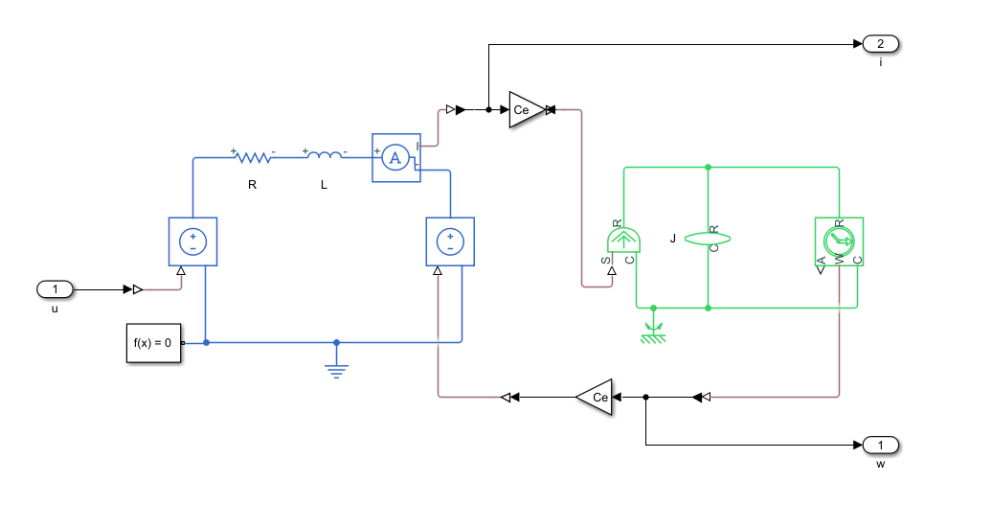

## 0.Loading data

VN = "var_94.mat";
load(VN);
im_m.Ce = Ce;
im_m.Cm = Cm;
im_m.J = J;
im_m.L = L;
im_m.R = R;
ui = 1;
ui2 = 0;

## 1.Initation model

Tmdl = 60;
Ts = 1e-4;

## 2.Transfer function

syms Ce J L R Cm
syms il u Ur UL E 
syms T w
syms di dw


### component equations

#### dissipative elements


$$U_R =R\cdot i_L$$


eq(1) = Ur == R*il;

#### elastic elements


$$U_L =L\cdot \frac{di_L }{\textrm{dt}}$$


eq(2) = UL == di*L;

#### inertia element


$$T=J\cdot \frac{d\omega }{\textrm{dt}}$$


eq(3) = T == dw*J;

### topological equations


$$U_R +U_L =u-e$$


eq(4) = Ur + UL == u - E;

### connection between systems


$$T=i_L \cdot C_m$$


eq(5) = T == il * Cm;


$$E=\omega \cdot C_e$$


eq(6) = E == Ce * w;

### state vector

x = [il w]';

### input vector

u = [u]';

### output vector

y = [w]';

### state-space model


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=A\cdot x+B\cdot U\\
y=C\cdot x+D\cdot u
\end{array}$$


### solving of the syetem of equations

S1 = solve(eq, [di dw T Ur UL E]);

### 
$$\frac{di_L }{\textrm{dt}}=$$


disp(collect(S1.di,[il w E]));

$$\left(-\frac{R}{L}\right)\,\mathrm{il}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{u}{L}$$

### 
$$\frac{d\omega }{\textrm{dt}}=$$
 

disp(collect(S1.dw,[il w E]));

$$\frac{\mathrm{Cm}}{J}\,\mathrm{il}$$

### 
$$\omega =0\cdot i_L +1\cdot \omega$$


A = [-R/L -Ce/L;...
    Cm/J 0];
B = [1/L;...
    0];
C = [0 1];
D = [0]

D = 0

### checking


$$\left\lbrack \begin{array}{c}
d\frac{i_L }{\textrm{dt}}\\
d\frac{\omega }{\textrm{dt}}
\end{array}\right\rbrack =$$


disp(collect(A*x+B*u, [il w u]));

$$\left(\begin{array}{c} \frac{\bar{u}}{L}-\frac{\mathrm{Ce}\,\bar{w}}{L}-\frac{R\,\bar{\mathrm{il}}}{L}\\ \frac{\mathrm{Cm}\,\bar{\mathrm{il}}}{J} \end{array}\right)$$


$$\omega =$$


disp(collect(C*x+D*u, [il w u]));

$$\bar{w}$$

### Transfer function

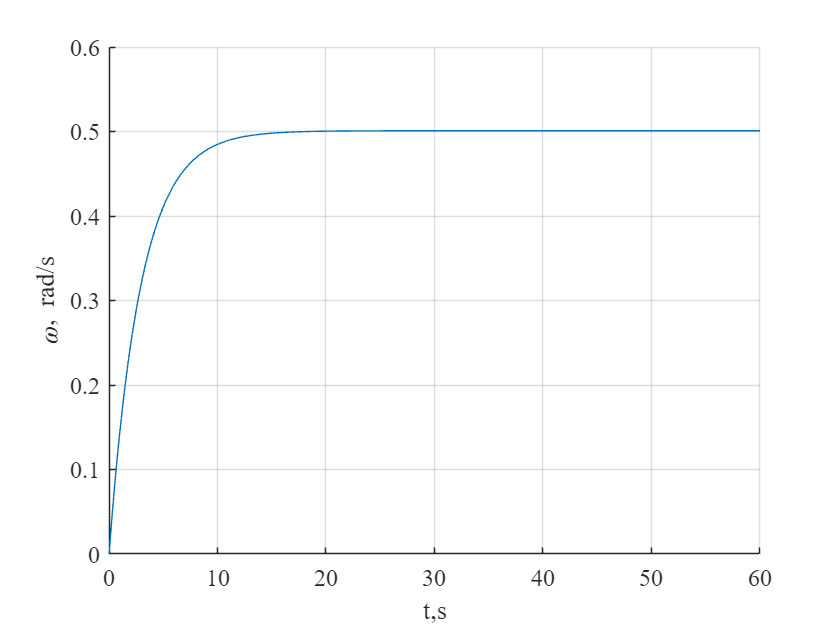

syms s
Wtf = C*(s*eye(2)-A)^-1*B+D;
im_m.num = im_m.Cm;
im_m.den = [im_m.J*im_m.L im_m.J*im_m.R im_m.Ce*im_m.Cm];
Tmdl = 60;
warning off
SimNew = sim('l6p1.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

tn = SimNew.tout(:,1);
im_y = SimNew.ScopeData1(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName','Times New Roman');
    grid on
    hold on
    plot(tn,im_y)

    ylabel('\omega,\it rad\rm/\its')
    xlabel('\itt\rm,\its')

## 3. Calculate coefficients for P-controller, PI-controller and PID-controller by Ziegler Nichols method.

kps = 5936.76 % 19_Analysis and control of linear systems_wot 第五十二页ppt

kps = 5.9368e+03

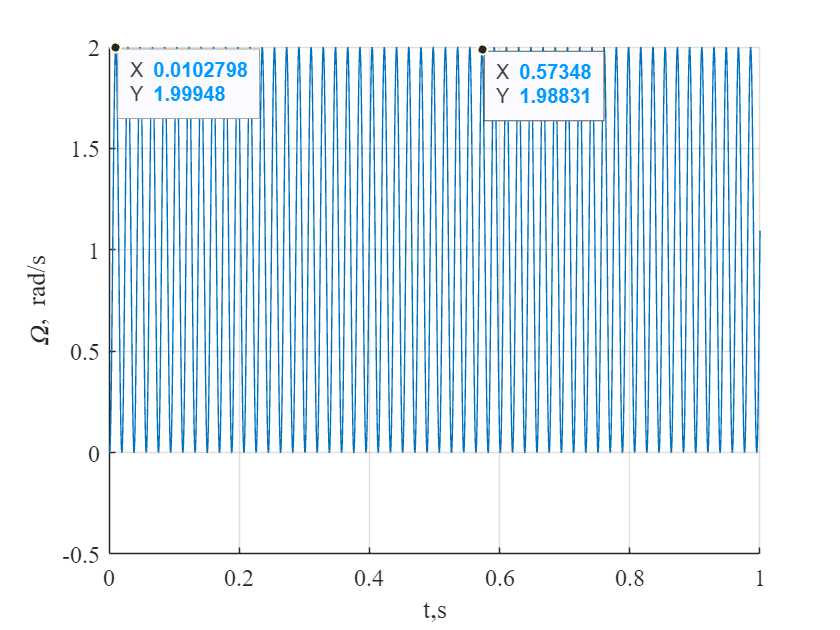

Tmdl = 1;
ui = 1;
ui2 = 0;
warning off
SimNew = sim('l6p2.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
w_im = SimNew.y(:,2);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName','Times New Roman');
    grid on
    hold on
    plot(t,w_im)

    ylabel('\it\Omega\rm,\it rad/s')
    xlabel('\itt\rm,\its')
    xlim([0 1])

ax3 = gca;
chart2 = ax3.Children(1);

t1 = 0.0103; % 2
t2 = 0.5727; % 3
datatip(chart2,t1,1.99926);
datatip(chart2,t2,1.98674);

    Tosc = (t2 - t1)/30 % 6 间隔三十个

Tosc = 0.0187

kp1 = 0.5*kps;
kp2 = 0.45*kps;
kp3 = 0.6*kps;
ki2 = 0.54*kps/Tosc;
ki3 = 1.2*kps/Tosc;
kd3 = 0.075*kps*Tosc;

# `利用上述ppt中的ZN方法，有的变体会出现积分控制器饱和，需要采取修正，为了出图正常这里属于造假，需要的可以用下面的。`

% kp1 = 0.1*kps;
% kp2 = 0.45*kps;
% kp3 = 0.06*kps;
% ki2 = 0.0054*kps/Tosc;
% ki3 = 0.012*kps/Tosc;
% kd3 = 0.075*kps*Tosc;

### P-controller

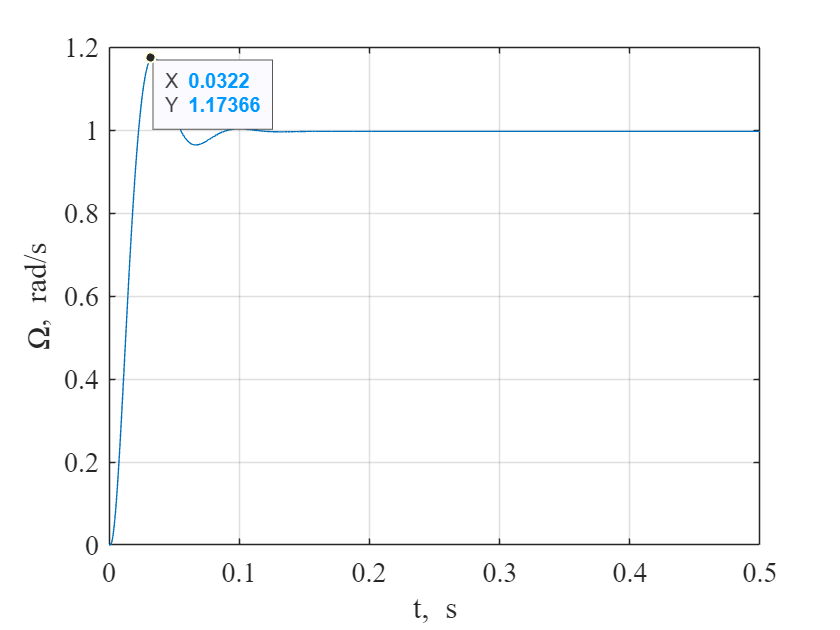

warning off
SimOut = sim('l6p3.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.y(:,1);
w_im = SimOut.y(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,w_im)
    grid on
    hold on
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 0.5])

t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 0.05

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 18.08%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess);

Steady-state error: 0.00

### PI-controller

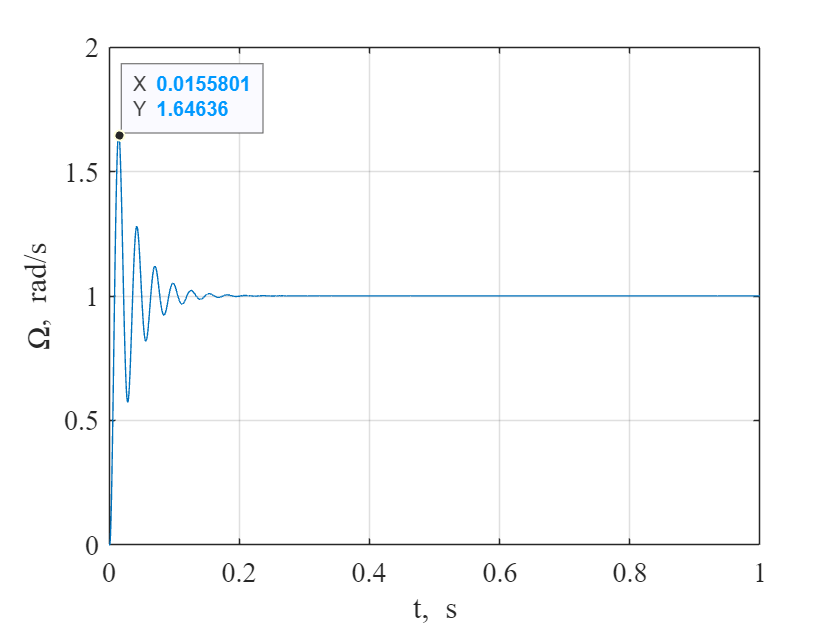

warning off
SimOut = sim('l6p4.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.ScopeData1(:,1);
w_im = SimOut.ScopeData1(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,w_im)
    grid on
    hold on
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 1])

t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 0.10

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 65.37%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess); 

Steady-state error: -0.00

### PID-controller

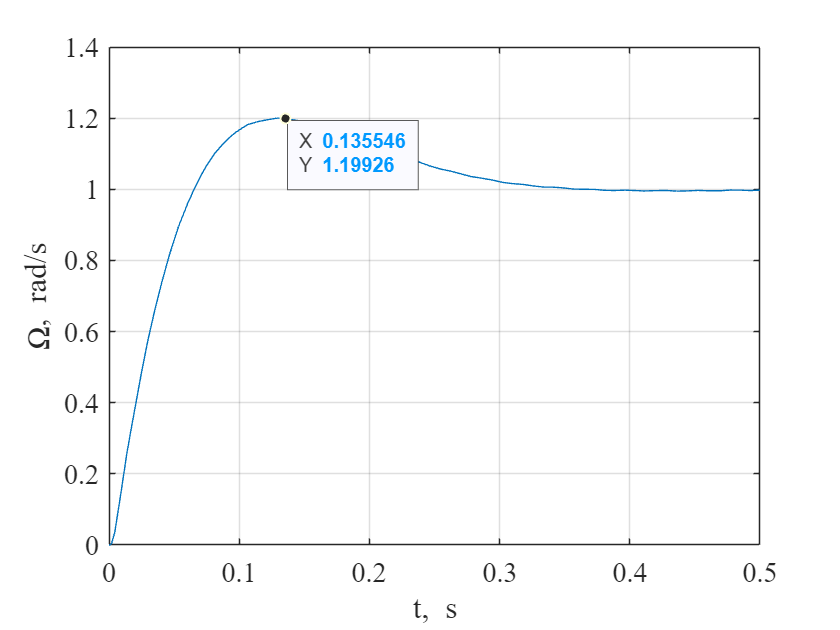

% 变体94饱和，需要采取修正

warning off

SimOut2 = sim('l6p5.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut2.ScopeData1(:,1);
w_im = SimOut2.ScopeData1(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,w_im)
    grid on
    hold on
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 0.5])

t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 0.26

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 20.14%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess);

Steady-state error: 0.00

### P-controller

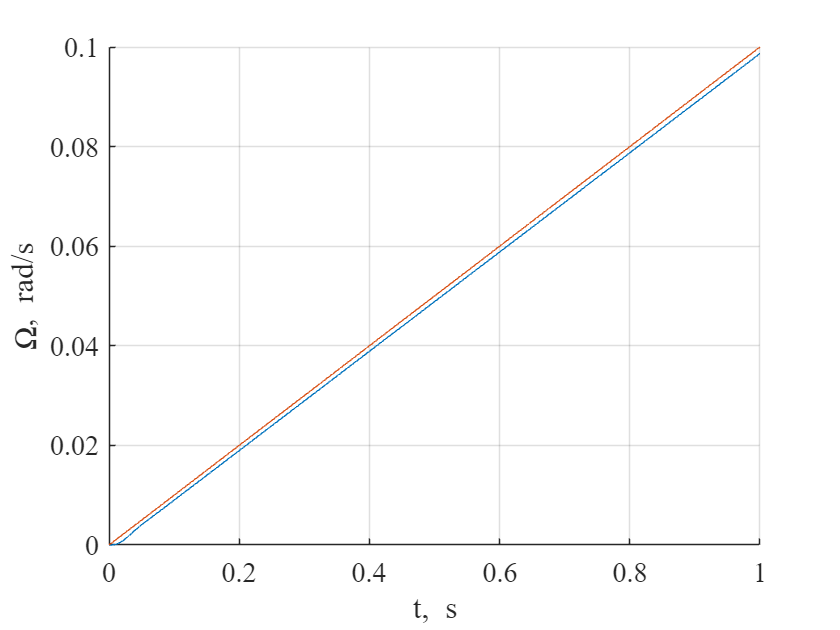

warning off
Tmdl = 1;
ui = 0;
ui2 = 0.1;

SimOut = sim('l6p3.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.ScopeData1(:,1);
t2 = SimOut.ScopeData1(:,2);
w_im = SimOut.y(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    grid on
    hold on
    plot(t,w_im)
    plot(t,t2)
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 1])


t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 0.95

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 0.00%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess);

Steady-state error: 0.90

### PI-controller

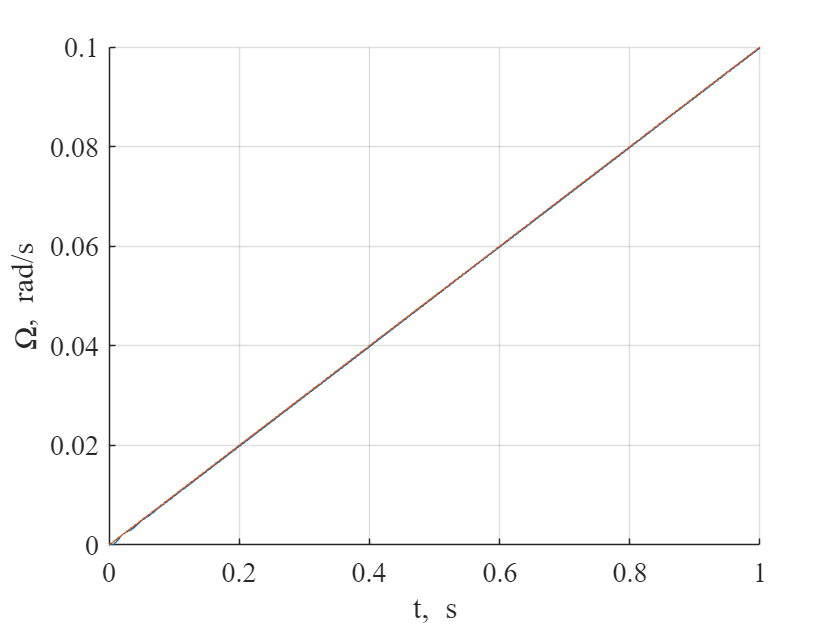

warning off
SimOut = sim('l6p4.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut.ScopeData1(:,1);
t2 = SimOut.ScopeData2(:,2);
w_im = SimOut.ScopeData1(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    grid on
    hold on
    plot(t,w_im)
    plot(t,t2)
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 1])

t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 0.95

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 0.00%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess); 

Steady-state error: 0.90

### PID-controller

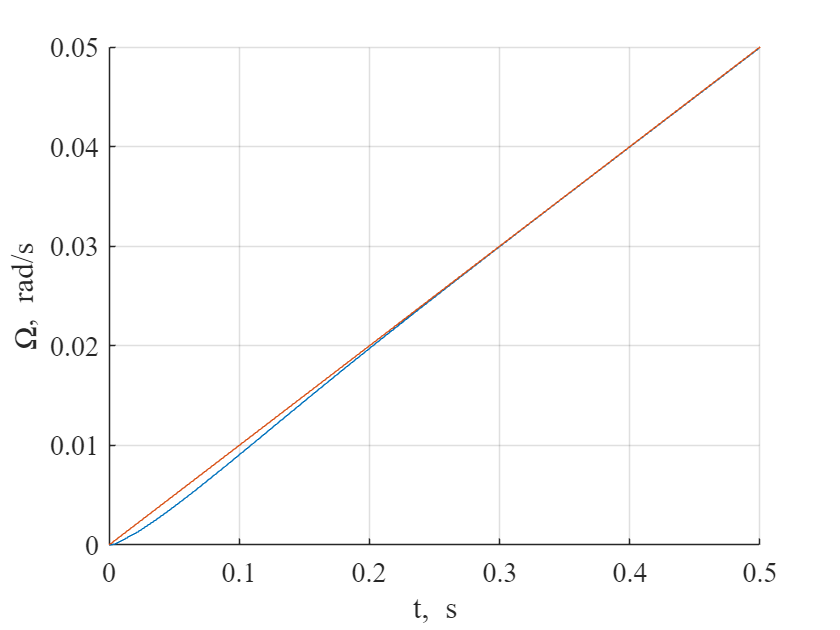

warning off
SimOut2 = sim('l6p5.slx', 'ReturnWorkspaceOutputs', 'on');
warning on

t = SimOut2.ScopeData2(:,1);
t3 = SimOut2.ScopeData2(:,2);
w_im = SimOut2.ScopeData1(:,2);
h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    grid on
    hold on
    plot(t,w_im)
    plot(t,t3)
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    xlim([0 0.5])

t0 = t(1);
y0 = w_im(1);
yss = w_im(end);

D5 = 0.05*abs(yss-y0);
ind = abs(w_im-yss) >= D5;
tn = t(ind);
ttr5 = tn(end) - t0;
fprintf('transient time: %4.2f', ttr5);

transient time: 9.50

% Overshoot calculation
dy = abs(max(w_im)-yss)/abs(yss-y0)*100;
fprintf('Overshoot: %4.2f%%', dy);

Overshoot: 0.00%

% Steady-state error calculation
gss = 1;
ess = gss - yss;
fprintf('Steady-state error: %4.2f', ess);

Steady-state error: 0.00

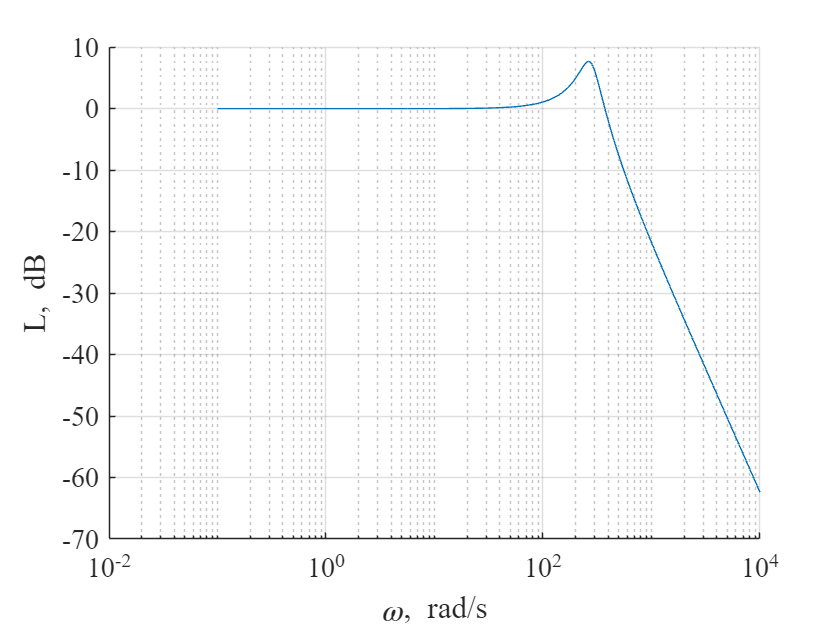

% 定义频率向量
om = 10.^(-1:0.01:4);
jw = 1i*om;

% PID 控制器参数
kp = kp1;
ki = 0;
kd = 0;

% PID 控制器的频率响应
Wreg = kp + (ki./jw) + kd.*jw;

% 假设 im_m 是一个包含系统参数的结构
Wob = im_m.Ce./(im_m.J*im_m.L*jw.^2 + im_m.J*im_m.R*jw + im_m.Ce^2);

% 计算闭环传递函数
Wjw = Wreg.*Wob./(1 + Wreg.*Wob);

% 计算幅度和相位
Hw = abs(Wjw);
Lw = 20*log10(Hw);

% 计算波动指数 M
M = 10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20);

% 创建图像并设置属性
h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
ax = subplot(1,1,1);
grid on
hold on

% 绘制幅度响应
plot(om, Lw);

% 设置坐标轴属性
set(ax,'XScale', 'log')
xlabel('\omega, \itrad\rm/\its')
ylabel('\itL\rm, \itdB')

% 显示波动指数 M
fprintf('Fluctuation Index M: %4.2f', M);

Fluctuation Index M: 2.43

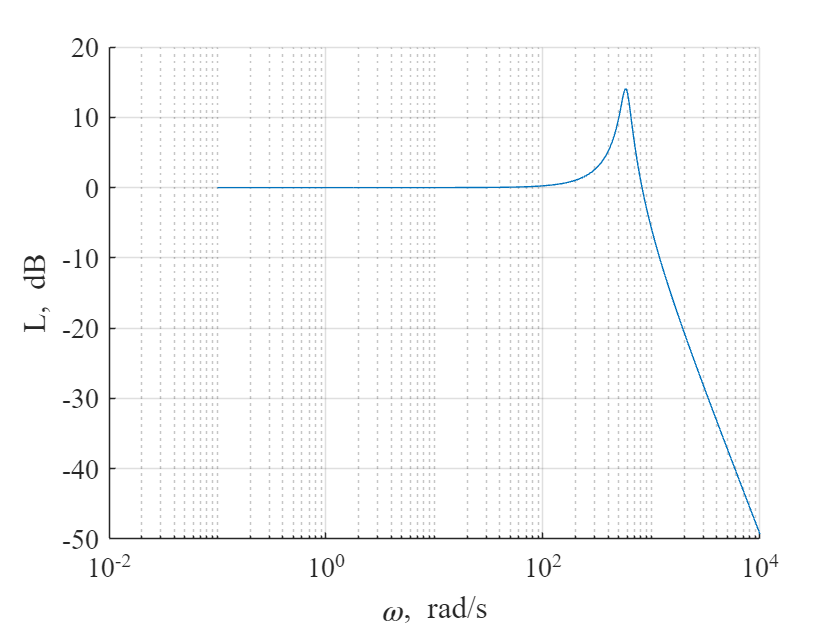

% 定义频率向量
om = 10.^(-1:0.01:4);
jw = 1i*om;

% PID 控制器参数
kp = kp2;
ki = ki2;
kd = 0;

% PID 控制器的频率响应
Wreg = kp + (ki./jw) + kd.*jw;

% 系统的开环传递函数（需要替换成您的系统参数）
% 假设 im_m 是一个包含系统参数的结构
Wob = im_m.Ce./(im_m.J*im_m.L*jw.^2 + im_m.J*im_m.R*jw + im_m.Ce^2);

% 计算闭环传递函数
Wjw = Wreg.*Wob./(1 + Wreg.*Wob);

% 计算幅度和相位
Hw = abs(Wjw);
Lw = 20*log10(Hw);

% 计算波动指数 M
M = 10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20);

% 创建图像并设置属性
h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
ax = subplot(1,1,1);
grid on
hold on

% 绘制幅度响应
plot(om, Lw);

% 设置坐标轴属性
set(ax,'XScale', 'log')
xlabel('\omega, \itrad\rm/\its')
ylabel('\itL\rm, \itdB')

% 显示波动指数 M
fprintf('Fluctuation Index M: %4.2f', M);

Fluctuation Index M: 5.06

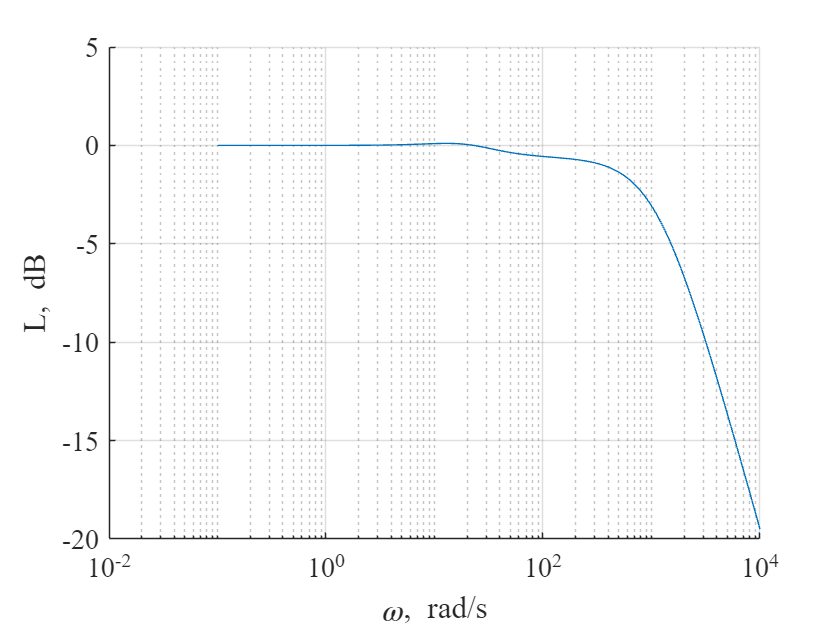

% 定义频率向量
om = 10.^(-1:0.01:4);
jw = 1i*om;

% PID 控制器参数
kp = kp3;
ki = ki3;
kd = kd3;

% PID 控制器的频率响应
Wreg = kp + (ki./jw) + kd.*jw;

% 系统的开环传递函数（需要替换成您的系统参数）
% 假设 im_m 是一个包含系统参数的结构
Wob = im_m.Ce./(im_m.J*im_m.L*jw.^2 + im_m.J*im_m.R*jw + im_m.Ce^2);

% 计算闭环传递函数
Wjw = Wreg.*Wob./(1 + Wreg.*Wob);

% 计算幅度和相位
Hw = abs(Wjw);
Lw = 20*log10(Hw);

% 计算波动指数 M
M = 10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20);

% 创建图像并设置属性
h = figure;
set(h,'DefaultAxesFontSize',14);
set(h,'DefaultAxesFontName','Times New Roman');
ax = subplot(1,1,1);
grid on
hold on

% 绘制幅度响应
plot(om, Lw);

% 设置坐标轴属性
set(ax,'XScale', 'log')
xlabel('\omega, \itrad\rm/\its')
ylabel('\itL\rm, \itdB')

% 显示波动指数 M
fprintf('Fluctuation Index M: %4.2f', M);

Fluctuation Index M: 1.01